# Histone ratios

**Author**: Scott Campit

## Summary

## Load data

clear all;
filepath = '~/Data/Expression/Combined/GCP to Metabolomics Modeling Data.xlsx';
% Read datasets into LASSO
ccle_gcp    = readtable(filepath, ...
                        'Sheet', 'CCLE LeRoy Xtrain', ...
                        'ReadRowNames', true);

ccle_gcp = standardizeMissing(ccle_gcp, 0);
ccle_metab  = readtable(filepath, ...
                        'Sheet', 'CCLE LeRoy Ytrain', ...
                        'ReadRowNames', true);

ccle_metab = standardizeMissing(ccle_metab, 0);
leroy_gcp   = readtable(filepath, ...
                        'Sheet', 'CCLE LeRoy Xtest', ...
                        'ReadRowNames', true);

leroy_gcp = standardizeMissing(leroy_gcp, 0);
leroy_metab = readtable(filepath, ...
                        'Sheet', 'CCLE LeRoy Ytest', ...
                        'ReadRowNames', true);

leroy_metab = standardizeMissing(leroy_metab, 0);

First let's save some of the mapping data

marker_labels = string(ccle_gcp.Properties.VariableNames);
metabolites = string(ccle_metab.Properties.VariableNames);

Then convert the data to double array

ccle_gcp    = table2array(ccle_gcp);
ccle_metab  = table2array(ccle_metab);
leroy_gcp   = table2array(leroy_gcp);
leroy_metab = table2array(leroy_metab);

## Heatmaps

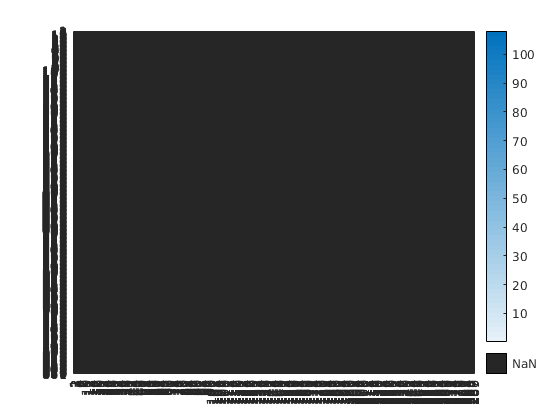

heatmap(ccle_gcp)